# The goal for this version is to introduce Phase variant LGN input

LGN is still fake, but will add more realistic factors...

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveFolder = [CurrentFolder '/Figures/Demo061921/'];
addpath(SaveFolder)
DataFolder = [CurrentFolder '/Figures/Demo042221/'];
addpath(DataFolder)

First read old network structure, get our desired Numbers of presyn neurons

load('NtWk_Archit.mat')
E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

N_EE = full(mean(sum(C_EE(E_Ind,:),2))); N_EI = full(mean(sum(C_EI(E_Ind,:),2))*0.75); %*0.75
N_IE = full(mean(sum(C_IE(I_Ind,:),2))); N_II = full(mean(sum(C_II(I_Ind,:),2))*0.75); %*0.75 Plan A:Original

Then use the new function to generate new network stucture


%% If now, we start computation below...
% Frst setup network
N_HC = 3;
% Number of E and I neurons
n_E_HC = 54; n_I_HC = 31; % per side of HC
N_E = n_E_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
% Grid sizes of E and I neurons;
Size_HC = 0.500; % in mm;
Size_E = Size_HC/n_E_HC; Size_I = Size_HC/n_I_HC;
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6;

% spatial indexes of E and I neurons
[NnE.X,NnE.Y] = V1Field_Generation(N_HC,1:N_E,'e');
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');

We are fixing boundary effect by connecting neurons to similar ODs

% Extended spatial indexes of E and I neurons (1HC each side)
Nex_E = n_E_HC^2 * (N_HC+2)^2; % neuron numbers In all
Nex_I = n_I_HC^2 * (N_HC+2)^2;
[NnEex.X,NnEex.Y] = V1Field_Generation(N_HC+2,1:Nex_E,'e');
[NnIex.X,NnIex.Y] = V1Field_Generation(N_HC+2,1:Nex_I,'i');


## Get a mapping between original and extended spatial indexs

% From original to extended
EMap_Ori2Ext = find(NnEex.X>n_E_HC & NnEex.X<=4*n_E_HC ...
                  & NnEex.Y>n_E_HC & NnEex.Y<=4*n_E_HC);
IMap_Ori2Ext = find(NnIex.X>n_I_HC & NnIex.X<=4*n_I_HC ...
                  & NnIex.Y>n_I_HC & NnIex.Y<=4*n_I_HC);
% from extended back to original: fold
% E
EMap_Ext2Ori = zeros(size(NnEex.X));
EMap_Ext2Ori(EMap_Ori2Ext) = 1:N_E;
CenterEHC = find(NnE.X>1*n_E_HC & NnE.X<=2*n_E_HC ...
               & NnE.Y>1*n_E_HC & NnE.Y<=2*n_E_HC);
CenterEHCRow = find(NnE.Y>1*n_E_HC & NnE.Y<=2*n_E_HC);
CenterEHCCol = find(NnE.X>1*n_E_HC & NnE.X<=2*n_E_HC);
EMap_Ext2Ori(NnEex.X>0*n_E_HC & NnEex.X<=1*n_E_HC ...
           & NnEex.Y>0*n_E_HC & NnEex.Y<=1*n_E_HC) = CenterEHC; % LL corner
EMap_Ext2Ori(NnEex.X>4*n_E_HC & NnEex.X<=5*n_E_HC ...
           & NnEex.Y>0*n_E_HC & NnEex.Y<=1*n_E_HC) = CenterEHC; % RL corner
EMap_Ext2Ori(NnEex.X>0*n_E_HC & NnEex.X<=1*n_E_HC ...
           & NnEex.Y>4*n_E_HC & NnEex.Y<=5*n_E_HC) = CenterEHC; % LH corner
EMap_Ext2Ori(NnEex.X>4*n_E_HC & NnEex.X<=5*n_E_HC ...
           & NnEex.Y>4*n_E_HC & NnEex.Y<=5*n_E_HC) = CenterEHC; % RH corner
EMap_Ext2Ori(NnEex.X>1*n_E_HC & NnEex.X<=4*n_E_HC ...
           & NnEex.Y>0*n_E_HC & NnEex.Y<=1*n_E_HC) = CenterEHCRow; % Low
EMap_Ext2Ori(NnEex.X>1*n_E_HC & NnEex.X<=4*n_E_HC ...
           & NnEex.Y>4*n_E_HC & NnEex.Y<=5*n_E_HC) = CenterEHCRow;    % High
EMap_Ext2Ori(NnEex.X>0*n_E_HC & NnEex.X<=1*n_E_HC ...
           & NnEex.Y>1*n_E_HC & NnEex.Y<=4*n_E_HC) = CenterEHCCol; % Left
EMap_Ext2Ori(NnEex.X>4*n_E_HC & NnEex.X<=5*n_E_HC ...
           & NnEex.Y>1*n_E_HC & NnEex.Y<=4*n_E_HC) = CenterEHCCol;    % Right
% I
IMap_Ext2Ori = zeros(size(NnIex.X));
IMap_Ext2Ori(IMap_Ori2Ext) = 1:N_I;
CenterIHC = find(NnI.X>1*n_I_HC & NnI.X<=2*n_I_HC ...
               & NnI.Y>1*n_I_HC & NnI.Y<=2*n_I_HC);
CenterIHCRow = find(NnI.Y>1*n_I_HC & NnI.Y<=2*n_I_HC);
CenterIHCCol = find(NnI.X>1*n_I_HC & NnI.X<=2*n_I_HC);
IMap_Ext2Ori(NnIex.X>0*n_I_HC & NnIex.X<=1*n_I_HC ...
           & NnIex.Y>0*n_I_HC & NnIex.Y<=1*n_I_HC) = CenterIHC; % LL corner
IMap_Ext2Ori(NnIex.X>4*n_I_HC & NnIex.X<=5*n_I_HC ...
           & NnIex.Y>0*n_I_HC & NnIex.Y<=1*n_I_HC) = CenterIHC; % RL corner
IMap_Ext2Ori(NnIex.X>0*n_I_HC & NnIex.X<=1*n_I_HC ...
           & NnIex.Y>4*n_I_HC & NnIex.Y<=5*n_I_HC) = CenterIHC; % LH corner
IMap_Ext2Ori(NnIex.X>4*n_I_HC & NnIex.X<=5*n_I_HC ...
           & NnIex.Y>4*n_I_HC & NnIex.Y<=5*n_I_HC) = CenterIHC; % RH corner
IMap_Ext2Ori(NnIex.X>1*n_I_HC & NnIex.X<=4*n_I_HC ...
           & NnIex.Y>0*n_I_HC & NnIex.Y<=1*n_I_HC) = CenterIHCRow; % Low
IMap_Ext2Ori(NnIex.X>1*n_I_HC & NnIex.X<=4*n_I_HC ...
           & NnIex.Y>4*n_I_HC & NnIex.Y<=5*n_I_HC) = CenterIHCRow; % High
IMap_Ext2Ori(NnIex.X>0*n_I_HC & NnIex.X<=1*n_I_HC ...
           & NnIex.Y>1*n_I_HC & NnIex.Y<=4*n_I_HC) = CenterIHCCol; % Left
IMap_Ext2Ori(NnIex.X>4*n_I_HC & NnIex.X<=5*n_I_HC ...
           & NnIex.Y>1*n_I_HC & NnIex.Y<=4*n_I_HC) = CenterIHCCol; % Right
% determine connections between E, I sparse metrices containing 0 or 1.
% Row_i Column_j means neuron j projects to neuron i add periodic boundary

C_EE_Fix_Bd = ConnectionMat_Fix_Boundary(N_E,NnEex,Size_E, EMap_Ori2Ext,...currentVec(2)^2
                                         N_E,NnEex,Size_E, EMap_Ext2Ori,...
                                         Peak_EE,SD_E,Dist_LB,1, round(N_EE));

Elapsed time is 18.979078 seconds.



C_EI_Fix_Bd = ConnectionMat_Fix_Boundary(N_E,NnEex,Size_E, EMap_Ori2Ext,...
                                         N_I,NnIex,Size_I, IMap_Ext2Ori,...
                                         Peak_I,SD_I,Dist_LB,0, round(N_EI));

Elapsed time is 9.069561 seconds.



C_IE_Fix_Bd = ConnectionMat_Fix_Boundary(N_I,NnIex,Size_I, IMap_Ori2Ext,...
                                         N_E,NnEex,Size_E, EMap_Ext2Ori,...
                                         Peak_I,SD_E,Dist_LB,0, round(N_IE));

Elapsed time is 9.718307 seconds.



C_II_Fix_Bd = ConnectionMat_Fix_Boundary(N_I,NnIex,Size_I, IMap_Ori2Ext,...
                                         N_I,NnIex,Size_I, IMap_Ext2Ori,...
                                         Peak_I,SD_I,Dist_LB,1, round(N_II));

CMatAll = struct('C_EE_Fix_Bd',C_EE_Fix_Bd,...
                 'C_EI_Fix_Bd',C_EI_Fix_Bd,...
                 'C_IE_Fix_Bd',C_IE_Fix_Bd,...
                 'C_II_Fix_Bd',C_II_Fix_Bd);

### Checking presyn neurons to goundary neurons. Can jump

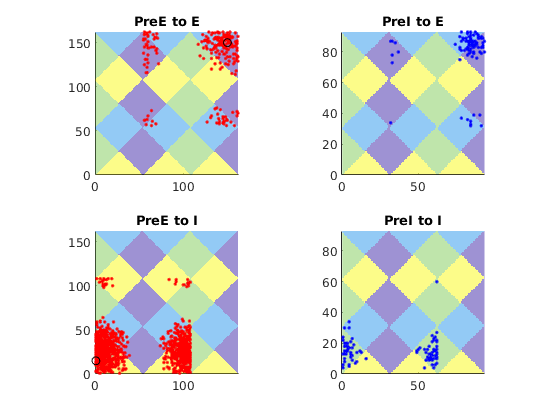

EX = 150; EY = 150;
EInd = find(NnE.X == EX & NnE.Y == EY);
PreEInd = find(C_EE_Fix_Bd(EInd,:));
PreIInd = find(C_EI_Fix_Bd(EInd,:));

figure
subplot 221
hold on
imagesc(OD_EMap,'AlphaData', .5);axis square
scatter(NnE.X(PreEInd),NnE.Y(PreEInd), 'r.')
scatter(EX,EY,'kO')
set(gca,'YDir','normal')
axis([0 n_E_HC * N_HC 0 n_E_HC * N_HC])
title('PreE to E')

subplot 222
hold on
imagesc(OD_IMap,'AlphaData', .5);axis square
scatter(NnI.X(PreIInd),NnI.Y(PreIInd), 'b.')
set(gca,'YDir','normal')
axis([0 n_I_HC * N_HC 0 n_I_HC * N_HC])
title('PreI to E')

IX = 1; IY = 15;
IInd = find(NnE.X == IX & NnE.Y == IY);
PreEInd = find(C_IE_Fix_Bd(IInd,:));
PreIInd = find(C_II_Fix_Bd(IInd,:));

subplot 223
hold on
imagesc(OD_EMap,'AlphaData', .5);axis square
scatter(NnE.X(PreEInd),NnE.Y(PreEInd), 'r.')
scatter(IX,IY,'kO')
set(gca,'YDir','normal')
axis([0 n_E_HC * N_HC 0 n_E_HC * N_HC])
title('PreE to I')

subplot 224
hold on
imagesc(OD_IMap,'AlphaData', .5);axis square
scatter(NnI.X(PreIInd),NnI.Y(PreIInd), 'b.')
set(gca,'YDir','normal')
axis([0 n_I_HC * N_HC 0 n_I_HC * N_HC])
title('PreI to I')

## Variables and Parameters

fixed parameters

p_EEFail = 0.2; S_amb = 0.01;
rE_amb = 0.500; rI_amb = 0.500;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms

gL_E = 1/20;  Ve = 14/3; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

NW Connectivity and L6 Input

S_EE = 0.024; S_EI = S_EE*1.6;  % was 1.5
S_II = 0.120; S_IE = S_II*0.153;
% L6 input
S_EL6 = 1/3*S_EE; S_IL6 = 1/3*S_IE;
rE_L6 = 0.25;     rI_L6 = rE_L6*3; %250hz for now

Make up LGN

S_Elgn = 2*S_EE;
S_Ilgn = 2*S_Elgn;
lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 

## Placeholder for old BG session...

## Now, with drive

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_E = zeros(size(NnE.X),'single');
OD_EMap = zeros(n_E_HC*N_HC,'single');
for NeuInd = 1:length(NnE.X)
OD_E(NeuInd) = OrientDom(ODNum,NnE.X(NeuInd),NnE.Y(NeuInd),n_E_HC);
OD_EMap(NnE.Y(NeuInd),NnE.X(NeuInd)) = OD_E(NeuInd);
end

OD_I = zeros(size(NnI.X),'single');
OD_IMap = zeros(n_I_HC*N_HC,'single');
for NeuInd = 1:length(NnI.X)
OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
StimulusFac = 1;
lgnE_Drive = [60,50,42,50]*4/1e3 * StimulusFac;
lgnI_Drive = min(lgnE_Drive);
lambda_E_drive = lgnE_Drive(OD_E)';
lambda_I_drive = lgnI_Drive;

L6E_Drive = [50 35 20 35]*50/1e3 * StimulusFac;
rE_L6_Drive = L6E_Drive(OD_E)';
rI_L6_Drive = 3*L6E_Drive(OD_I)';


% Making Poisson here/Reading
T = 10000; dt = 0.1;
TimeFrac = 0.05;
LGNCurInp = 0;

lgnE_Events = PoissonInputForNetwork(N_E,lambda_E_drive*(1-LGNCurInp),T*TimeFrac,dt);
lgnI_Events = PoissonInputForNetwork(N_I,lambda_I_drive*(1-LGNCurInp),T*TimeFrac,dt);
AmbE_Events = PoissonInputForNetwork(N_E,rE_amb,T*TimeFrac,dt);
AmbI_Events = PoissonInputForNetwork(N_I,rI_amb,T*TimeFrac,dt);

% L6 is much more specific!!! We will make a sum of Poisson and constant
L6CurInp = 0;
L6E_Events  = PoissonInputForNetwork(N_E,rE_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);
L6I_Events  = PoissonInputForNetwork(N_I,rI_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);


### Incorporate Phase:

Use an updating vector for each E cell to reflect its on-off phase

Directly pull lgnEevents and do multiplication with the phase factor

LGNFreq = 2; % 2Hz
tMod = 1e3/LGNFreq; MaxOnPhase = tMod/2;% Each Cycle lasts for 500 ms
PhaseE = tMod*rand(N_E,1);
PhaseFR = [90 67.5 45 67.5,    0  22.5 45 22.5] *4/1e3 * StimulusFac;
lambda_EOn_drive  = PhaseFR(OD_E)';
lambda_EOff_drive = PhaseFR(OD_E+max(OD_E))';

Simulation of Drive

Then make a transfer between neurons in HCs and 10*10 pixels

%% Network Simulation
SimulationT = 5000; 
% E-to-E delay time
T_EEDly = .9; N_EEDly = floor(T_EEDly/dt);
T_IEDly = .5; N_IEDly = floor(T_IEDly/dt);
T_EIDly = .5; N_EIDly = floor(T_EIDly/dt);
% % The initial states
% InSs = load('Initials_L6.mat');
% RefTimeE = InSs.RefTimeE; VE = InSs.VE; SpE = InSs.SpE; GE_ampa_R = InSs.GE_ampa_R; GE_nmda_R = InSs.GE_nmda_R; GE_gaba_R = InSs.GE_gaba_R;
% GE_ampa_D = InSs.GE_ampa_D; GE_nmda_D = InSs.GE_nmda_D; GE_gaba_D = InSs.GE_gaba_D;
% RefTimeI = InSs.RefTimeI; VI = InSs.VI; SpI = InSs.SpI; GI_ampa_R = InSs.GI_ampa_R; GI_nmda_R = InSs.GI_nmda_R; GI_gaba_R = InSs.GI_gaba_R;
% GI_ampa_D = InSs.GI_ampa_D; GI_nmda_D = InSs.GI_nmda_D; GI_gaba_D = InSs.GI_gaba_D;
% EEDlyRcd = sparse(N_E,N_EEDly);

% The initial states, for more simulation 
load(['LargeNWFixIni.mat'],'EndState');
%load('IniTest.mat');
RefTimeE = EndState{1}; VE = EndState{2}; SpE = EndState{3}; GE_ampa_R = EndState{4}; GE_nmda_R = EndState{5}; GE_gaba_R = EndState{6};
                                                             GE_ampa_D = EndState{7}; GE_nmda_D = EndState{8}; GE_gaba_D = EndState{9};
RefTimeI = EndState{10}; VI = EndState{11}; SpI = EndState{12}; GI_ampa_R = EndState{13}; GI_nmda_R = EndState{14}; GI_gaba_R = EndState{15};
                                                                GI_ampa_D = EndState{16}; GI_nmda_D = EndState{17}; GI_gaba_D = EndState{18};
if N_EEDly>=size(EndState{19},2)
EEDlyRcd = [EndState{19},zeros(N_E,N_EEDly-size(EndState{19},2))]; 
else
    EEDlyRcd = EndState{19}(:,1:N_EEDly);
end
if N_IEDly>=size(EndState{20},2)
IEDlyRcd = [EndState{20},zeros(N_I,N_IEDly-size(EndState{20},2))]; 
else
    IEDlyRcd = EndState{20}(:,1:N_IEDly);
end
EIDlyRcd = ones(N_E,N_EIDly);
% Create sliding windows
sampleT = 50;
Sliding = 50;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);
WinNum = length(Wins);
sampleN = floor(Sliding/dt); % sample each 2 ms
SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1));
%NWTrace.Wins = {Wins};

MaxInpBin = floor(T*TimeFrac/dt);

The biggest problem here is the access to the input matrices

So I do the following:

For every 100ms (1000 bins), first pre-compute input matrices for all (E ampa, Enmda, Iampa, Inmda), then feed into iteration algorithm

But to accelerate, we exclude L6 Current Input at first...

TPar = 10;
for TSec = 1:TPar
tic
for TimeN = 1:floor(T/dt/TPar)
    % Zero: Use Phase vec to determine different lgn phases for E neurons
    PhaseE = mod(PhaseE + dt,tMod);  
    AdjlgnE = PhaseFR(floor(PhaseE/MaxOnPhase)*ODNum + OD_E')';
    % First, Get input matrices from series
    InpWin = 100; FrameNum = floor(InpWin/dt);
    FrameInd = mod(TimeN, FrameNum);
    if FrameInd == 0
    FrameInd = FrameNum;
    end
    RandTimBin = randi([1 MaxInpBin+1],6,FrameNum);
    if FrameInd  == 1 % if the first frame, recompute input mats
        EampaInp = single(full(S_Elgn * (lgnE_Events(:,RandTimBin(1,:)) .*AdjlgnE./lambda_E_drive...
                      + lambda_E_drive*dt*LGNCurInp) ...
                      + S_amb  * AmbE_Events(:,RandTimBin(3,:)) ...
                      + S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_ampa)); %  * rhoE_ampa
        IampaInp = single(full(S_Ilgn * (lgnI_Events(:,RandTimBin(2,:)) + lambda_I_drive*dt*LGNCurInp) ...
                      + S_amb  * AmbI_Events(:,RandTimBin(4,:)) ...
                      + S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_ampa)); %  * rhoI_ampa
        
        EnmdaInp = single(full(S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_nmda)); % 
        InmdaInp = single(full(S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_nmda));
        
    end
    
   
%      lgnEVec = zeros(N_E,1);lgnIVec = zeros(N_I,1);
%      AmbEVec = zeros(N_E,1);AmbIVec = zeros(N_I,1);
%      L6EVec = zeros(N_E,1); L6IVec = zeros(N_I,1);
   [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
                             oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
          oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
                             oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
                             oEEDlyRcd,oIEDlyRcd, oEIDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
   V1NetworkUpdate_Ver3_Drive_PoissonRead_EEnIEnEIDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
                                                        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
                                                        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
                                                        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
                                                        EEDlyRcd,IEDlyRcd, EIDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
                          C_EE_Fix_Bd,C_EI_Fix_Bd,C_IE_Fix_Bd,C_II_Fix_Bd,...
                          S_EE,S_EI,S_IE,S_II,...
                          tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
                          dt,p_EEFail,...
                          gL_E,Ve,rhoE_ampa,rhoE_nmda,...
                          gL_I,Vi,rhoI_ampa,rhoI_nmda,...
                          EampaInp(:,FrameInd), IampaInp(:,FrameInd),...
                          EnmdaInp(:,FrameInd), InmdaInp(:,FrameInd));
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd; EIDlyRcd = oEIDlyRcd;
    
    
     
    % Record Every Time time window
    RecordNum = floor(sampleT/dt);
    RecordInd = mod(TimeN, RecordNum);
    SampleRate = 0.1; % Can't be too small for multiple phases
    if RecordInd == 1
        clear E_Sp I_Sp mVETemp mVITemp
        E_Sp = [];
        I_Sp = [];
        mVETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        mVITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        mVRecordInd = 1;        
    elseif RecordInd == 0 
        NWTrace(SampleInd).mVEs = mVETemp;
        NWTrace(SampleInd).mVIs = mVITemp;
        
        NWTrace(SampleInd).SpEs = E_Sp;
        NWTrace(SampleInd).SpIs= I_Sp;
              
        SampleInd = SampleInd + 1
        %sum(isnan(oVE))/N_E
        FrENow = size(E_Sp,1)/N_E/sampleT*1000
        FrINow = size(I_Sp,1)/N_I/sampleT*1000
        toc        
    end
    E_Sp = single([E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]]);
    I_Sp = single([I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]]);
    
    if mod(TimeN,floor(1/SampleRate)) == 5
        mVETemp(:,mVRecordInd) = oVE;
        mVITemp(:,mVRecordInd) = oVI;
        mVRecordInd = mVRecordInd + 1; 
    end
    
%     if sum(isnan(oVE))>0.80*N_E
%         BlowUp = true;
%         disp('warning!: Network exploded')
%         break
%     end
    
    % the end of iteration
end
toc
text = ['DriveWkSp_FixPreSynN_LowIto_PhaseLGNT_Bdr' num2str(TSec) 's.mat'];
EndState = {RefTimeE, VE, SpE, GE_ampa_R, GE_nmda_R, GE_gaba_R, GE_ampa_D, GE_nmda_D, GE_gaba_D,...
            RefTimeI, VI, SpI, GI_ampa_R, GI_nmda_R, GI_gaba_R, GI_ampa_D, GI_nmda_D, GI_gaba_D,...
            EEDlyRcd, IEDlyRcd};
save([SaveFolder text],'NWTrace','EndState','CMatAll','-v7.3')
save([SaveFolder,'DriveWkSp_FixPreSynN_LowIto_EndPhase.mat'],'PhaseE');
clear NWTrace
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1));
end

SampleInd = 2

FrENow = 19.7897

FrINow = 73.6270

Elapsed time is 2.479858 seconds.


SampleInd = 3

FrENow = 16.4144

FrINow = 69.0484

Elapsed time is 4.330394 seconds.


SampleInd = 4

FrENow = 16.6629

FrINow = 70.2694

Elapsed time is 6.692847 seconds.


SampleInd = 5

FrENow = 16.6613

FrINow = 71.1319

Elapsed time is 8.561522 seconds.


SampleInd = 6

FrENow = 15.3582

FrINow = 67.5199

Elapsed time is 10.765256 seconds.


SampleInd = 7

FrENow = 16.4723

FrINow = 70.2786

Elapsed time is 12.651808 seconds.


SampleInd = 8

FrENow = 16.5539

FrINow = 70.3688

Elapsed time is 15.044344 seconds.


SampleInd = 9

FrENow = 16.5958

FrINow = 70.3711

Elapsed time is 16.835755 seconds.


SampleInd = 10

FrENow = 14.7660

FrINow = 65.6191

Elapsed time is 19.029300 seconds.


SampleInd = 11

FrENow = 16.6400

FrINow = 70.6116

Elapsed time is 20.901714 seconds.


SampleInd = 12

FrENow = 16.1911

FrINow = 69.7052

Elapsed time is 23.223472 seconds.


SampleInd = 13

FrENow = 16.9220

FrINow = 71.2383

Elapsed time is 25.042462 seconds.


SampleInd = 14

FrENow = 16.5371

FrINow = 70.8151

Elapsed time is 27.245174 seconds.


SampleInd = 15

FrENow = 16.0982

FrINow = 70.0728

Elapsed time is 29.039925 seconds.


SampleInd = 16

FrENow = 15.8490

FrINow = 69.0554

Elapsed time is 31.223394 seconds.


SampleInd = 17

FrENow = 16.0440

FrINow = 69.4416

Elapsed time is 33.072016 seconds.


SampleInd = 18

FrENow = 16.2003

FrINow = 69.1664

Elapsed time is 35.362204 seconds.


SampleInd = 19

FrENow = 16.2620

FrINow = 69.6127

Elapsed time is 37.218733 seconds.


SampleInd = 20

FrENow = 16.4998

FrINow = 69.9757

Elapsed time is 39.508448 seconds.


SampleInd = 21

FrENow = 16.6789

FrINow = 70.4729

Elapsed time is 41.384034 seconds.


Elapsed time is 41.384821 seconds.


SampleInd = 22

FrENow = 16.4137

FrINow = 70.0752

Elapsed time is 2.281840 seconds.


SampleInd = 23

FrENow = 16.3923

FrINow = 70.2093

Elapsed time is 4.104326 seconds.


SampleInd = 24

FrENow = 16.3756

FrINow = 69.8370

Elapsed time is 6.458155 seconds.


SampleInd = 25

FrENow = 16.5478

FrINow = 70.5700

Elapsed time is 8.394241 seconds.


SampleInd = 26

FrENow = 15.6592

FrINow = 68.5374

Elapsed time is 10.722533 seconds.


SampleInd = 27

FrENow = 15.8490

FrINow = 68.7686

Elapsed time is 12.491360 seconds.


SampleInd = 28

FrENow = 16.8640

FrINow = 70.8498

Elapsed time is 14.733760 seconds.


SampleInd = 29

FrENow = 16.7459

FrINow = 71.0857

Elapsed time is 16.657874 seconds.


SampleInd = 30

FrENow = 16.1309

FrINow = 69.2658

Elapsed time is 18.859910 seconds.


SampleInd = 31

FrENow = 15.5464

FrINow = 67.4945

Elapsed time is 20.707159 seconds.


SampleInd = 32

FrENow = 17.0729

FrINow = 71.5181

Elapsed time is 23.032624 seconds.


SampleInd = 33

FrENow = 16.8054

FrINow = 70.9909

Elapsed time is 24.941258 seconds.


SampleInd = 34

FrENow = 16.2216

FrINow = 69.8994

Elapsed time is 27.221104 seconds.


SampleInd = 35

FrENow = 16.8183

FrINow = 71.2892

Elapsed time is 29.151174 seconds.


SampleInd = 36

FrENow = 15.6485

FrINow = 68.2229

Elapsed time is 31.453992 seconds.


SampleInd = 37

FrENow = 16.5005

FrINow = 70.1561

Elapsed time is 33.269967 seconds.


SampleInd = 38

FrENow = 16.0882

FrINow = 68.9906

Elapsed time is 35.521882 seconds.


SampleInd = 39

FrENow = 17.3891

FrINow = 72.4246

Elapsed time is 37.396208 seconds.


SampleInd = 40

FrENow = 15.7240

FrINow = 67.9824

Elapsed time is 39.681452 seconds.


SampleInd = 41

FrENow = 16.6537

FrINow = 70.1376

Elapsed time is 41.521994 seconds.


Elapsed time is 41.522741 seconds.


SampleInd = 42

FrENow = 16.4647

FrINow = 69.8855

Elapsed time is 2.343979 seconds.


SampleInd = 43

FrENow = 16.5859

FrINow = 70.5723

Elapsed time is 4.203008 seconds.


SampleInd = 44

FrENow = 16.6949

FrINow = 71.3308

Elapsed time is 6.609483 seconds.


SampleInd = 45

FrENow = 15.9686

FrINow = 69.4855

Elapsed time is 8.543099 seconds.


SampleInd = 46

FrENow = 17.0226

FrINow = 71.9066

Elapsed time is 10.907540 seconds.


SampleInd = 47

FrENow = 16.4960

FrINow = 70.2046

Elapsed time is 12.850705 seconds.


SampleInd = 48

FrENow = 16.0623

FrINow = 68.9606

Elapsed time is 15.192142 seconds.


SampleInd = 49

FrENow = 16.1454

FrINow = 69.3745

Elapsed time is 17.019351 seconds.


SampleInd = 50

FrENow = 16.6171

FrINow = 70.1931

Elapsed time is 19.333626 seconds.


SampleInd = 51

FrENow = 16.2544

FrINow = 69.4947

Elapsed time is 21.219640 seconds.


SampleInd = 52

FrENow = 16.2071

FrINow = 69.4207

Elapsed time is 23.504502 seconds.


SampleInd = 53

FrENow = 16.8709

FrINow = 71.4464

Elapsed time is 25.349795 seconds.


SampleInd = 54

FrENow = 16.2795

FrINow = 69.9572

Elapsed time is 27.645755 seconds.


SampleInd = 55

FrENow = 16.3352

FrINow = 70.3203

Elapsed time is 29.449841 seconds.


SampleInd = 56

FrENow = 16.1324

FrINow = 69.6034

Elapsed time is 31.737813 seconds.


SampleInd = 57

FrENow = 16.6888

FrINow = 71.3007

Elapsed time is 33.636288 seconds.


SampleInd = 58

FrENow = 15.9153

FrINow = 68.7571

Elapsed time is 35.867437 seconds.


SampleInd = 59

FrENow = 16.3466

FrINow = 69.7537

Elapsed time is 37.749003 seconds.


SampleInd = 60

FrENow = 16.0380

FrINow = 68.9721

Elapsed time is 39.936953 seconds.


SampleInd = 61

FrENow = 16.6568

FrINow = 70.0728

Elapsed time is 41.820022 seconds.


Elapsed time is 41.820751 seconds.


SampleInd = 62

FrENow = 17.0066

FrINow = 72.1378

Elapsed time is 2.356424 seconds.


SampleInd = 63

FrENow = 17.1635

FrINow = 72.4824

Elapsed time is 4.245657 seconds.


SampleInd = 64

FrENow = 15.1486

FrINow = 67.4876

Elapsed time is 6.517088 seconds.


SampleInd = 65

FrENow = 16.7147

FrINow = 71.3747

Elapsed time is 8.365951 seconds.


SampleInd = 66

FrENow = 15.8779

FrINow = 68.6970

Elapsed time is 10.638165 seconds.


SampleInd = 67

FrENow = 16.2468

FrINow = 69.7537

Elapsed time is 12.529380 seconds.


SampleInd = 68

FrENow = 17.0340

FrINow = 71.6592

Elapsed time is 14.808372 seconds.


SampleInd = 69

FrENow = 16.3595

FrINow = 70.1676

Elapsed time is 16.599686 seconds.


SampleInd = 70

FrENow = 15.3772

FrINow = 67.3303

Elapsed time is 18.795508 seconds.


SampleInd = 71

FrENow = 16.4693

FrINow = 69.8670

Elapsed time is 20.659159 seconds.


SampleInd = 72

FrENow = 17.3983

FrINow = 72.5078

Elapsed time is 23.033511 seconds.


SampleInd = 73

FrENow = 15.6760

FrINow = 68.2738

Elapsed time is 24.845908 seconds.


SampleInd = 74

FrENow = 16.6126

FrINow = 70.7619

Elapsed time is 27.100131 seconds.


SampleInd = 75

FrENow = 16.6888

FrINow = 71.2637

Elapsed time is 28.873619 seconds.


SampleInd = 76

FrENow = 16.1706

FrINow = 69.6797

Elapsed time is 31.170997 seconds.


SampleInd = 77

FrENow = 16.1698

FrINow = 69.3699

Elapsed time is 33.034418 seconds.


SampleInd = 78

FrENow = 16.7414

FrINow = 70.7249

Elapsed time is 35.302664 seconds.


SampleInd = 79

FrENow = 16.4594

FrINow = 70.5122

Elapsed time is 37.209739 seconds.


SampleInd = 80

FrENow = 16.5562

FrINow = 70.2625

Elapsed time is 39.482357 seconds.


SampleInd = 81

FrENow = 16.5767

FrINow = 70.5954

Elapsed time is 41.233092 seconds.


Elapsed time is 41.233805 seconds.


SampleInd = 82

FrENow = 16.3443

FrINow = 70.0220

Elapsed time is 2.228524 seconds.


SampleInd = 83

FrENow = 15.2385

FrINow = 67.2147

Elapsed time is 3.982119 seconds.


SampleInd = 84

FrENow = 16.7802

FrINow = 70.6648

Elapsed time is 6.359865 seconds.


SampleInd = 85

FrENow = 16.8442

FrINow = 71.9112

Elapsed time is 8.265460 seconds.


SampleInd = 86

FrENow = 15.4443

FrINow = 67.5338

Elapsed time is 10.559118 seconds.


SampleInd = 87

FrENow = 16.8145

FrINow = 71.2221

Elapsed time is 12.516466 seconds.


SampleInd = 88

FrENow = 16.4213

FrINow = 70.3735

Elapsed time is 14.803949 seconds.


SampleInd = 89

FrENow = 15.8566

FrINow = 68.7733

Elapsed time is 16.633594 seconds.


SampleInd = 90

FrENow = 16.8168

FrINow = 70.9770

Elapsed time is 18.983463 seconds.


SampleInd = 91

FrENow = 16.2856

FrINow = 69.5572

Elapsed time is 20.870477 seconds.


SampleInd = 92

FrENow = 16.6781

FrINow = 70.8914

Elapsed time is 23.137104 seconds.


SampleInd = 93

FrENow = 16.3039

FrINow = 69.7907

Elapsed time is 24.876943 seconds.


SampleInd = 94

FrENow = 16.1279

FrINow = 69.9988

Elapsed time is 27.168033 seconds.


SampleInd = 95

FrENow = 16.6705

FrINow = 70.6093

Elapsed time is 28.938642 seconds.


SampleInd = 96

FrENow = 15.9290

FrINow = 68.8241

Elapsed time is 31.146401 seconds.


SampleInd = 97

FrENow = 17.3929

FrINow = 72.9194

Elapsed time is 32.988313 seconds.


SampleInd = 98

FrENow = 15.1410

FrINow = 66.9465

Elapsed time is 35.239377 seconds.


SampleInd = 99

FrENow = 17.4059

FrINow = 72.4338

Elapsed time is 37.085324 seconds.


SampleInd = 100

FrENow = 15.8611

FrINow = 68.3940

Elapsed time is 39.329379 seconds.


SampleInd = 101

FrENow = 16.7916

FrINow = 70.8984

Elapsed time is 41.189584 seconds.


Elapsed time is 41.190380 seconds.


SampleInd = 102

FrENow = 16.4480

FrINow = 70.2902

Elapsed time is 2.362656 seconds.


SampleInd = 103

FrENow = 16.3016

FrINow = 69.8578

Elapsed time is 4.212383 seconds.


SampleInd = 104

FrENow = 16.5783

FrINow = 70.6856

Elapsed time is 6.559352 seconds.


SampleInd = 105

FrENow = 16.5409

FrINow = 70.7966

Elapsed time is 8.491631 seconds.


SampleInd = 106

FrENow = 15.5464

FrINow = 68.1905

Elapsed time is 10.697601 seconds.


SampleInd = 107

FrENow = 16.4053

FrINow = 69.7560

Elapsed time is 12.606616 seconds.


SampleInd = 108

FrENow = 15.4527

FrINow = 67.4783

Elapsed time is 14.885274 seconds.


SampleInd = 109

FrENow = 16.7916

FrINow = 70.7157

Elapsed time is 16.753734 seconds.


SampleInd = 110

FrENow = 16.7749

FrINow = 70.9978

Elapsed time is 19.106105 seconds.


SampleInd = 111

FrENow = 15.7080

FrINow = 68.0264

Elapsed time is 20.890766 seconds.


SampleInd = 112

FrENow = 16.2323

FrINow = 69.6635

Elapsed time is 23.117121 seconds.


SampleInd = 113

FrENow = 16.6011

FrINow = 70.8267

Elapsed time is 24.991072 seconds.


SampleInd = 114

FrENow = 16.2155

FrINow = 69.9387

Elapsed time is 27.200876 seconds.


SampleInd = 115

FrENow = 16.5813

FrINow = 70.4613

Elapsed time is 29.103509 seconds.


SampleInd = 116

FrENow = 16.0280

FrINow = 68.8403

Elapsed time is 31.294159 seconds.


SampleInd = 117

FrENow = 16.5943

FrINow = 70.6440

Elapsed time is 33.118845 seconds.


SampleInd = 118

FrENow = 15.7674

FrINow = 68.7131

Elapsed time is 35.417762 seconds.


SampleInd = 119

FrENow = 16.8618

FrINow = 71.4903

Elapsed time is 37.265479 seconds.


SampleInd = 120

FrENow = 15.3056

FrINow = 67.1893

Elapsed time is 39.409734 seconds.


SampleInd = 121

FrENow = 16.7802

FrINow = 70.3503

Elapsed time is 41.155667 seconds.


Elapsed time is 41.156349 seconds.


SampleInd = 122

FrENow = 17.0088

FrINow = 71.3470

Elapsed time is 2.322058 seconds.


SampleInd = 123

FrENow = 15.8543

FrINow = 68.6785

Elapsed time is 4.160692 seconds.


SampleInd = 124

FrENow = 16.4426

FrINow = 70.2324

Elapsed time is 6.395159 seconds.


SampleInd = 125

FrENow = 16.3626

FrINow = 70.0890

Elapsed time is 8.313270 seconds.


SampleInd = 126

FrENow = 16.2841

FrINow = 70.0382

Elapsed time is 10.569290 seconds.


SampleInd = 127

FrENow = 16.5996

FrINow = 70.7041

Elapsed time is 12.419002 seconds.


SampleInd = 128

FrENow = 16.3733

FrINow = 70.0752

Elapsed time is 14.741690 seconds.


SampleInd = 129

FrENow = 16.4053

FrINow = 70.4405

Elapsed time is 16.623276 seconds.


SampleInd = 130

FrENow = 15.2614

FrINow = 66.9118

Elapsed time is 18.894964 seconds.


SampleInd = 131

FrENow = 16.4319

FrINow = 69.5525

Elapsed time is 20.781424 seconds.


SampleInd = 132

FrENow = 17.2215

FrINow = 71.9366

Elapsed time is 23.097485 seconds.


SampleInd = 133

FrENow = 16.0349

FrINow = 69.4994

Elapsed time is 24.955729 seconds.


SampleInd = 134

FrENow = 16.3222

FrINow = 70.2440

Elapsed time is 27.235221 seconds.


SampleInd = 135

FrENow = 16.5234

FrINow = 70.5746

Elapsed time is 29.119672 seconds.


SampleInd = 136

FrENow = 16.3519

FrINow = 70.2301

Elapsed time is 31.360996 seconds.


SampleInd = 137

FrENow = 16.3085

FrINow = 70.0937

Elapsed time is 33.124071 seconds.


SampleInd = 138

FrENow = 15.7087

FrINow = 68.0749

Elapsed time is 35.376051 seconds.


SampleInd = 139

FrENow = 16.8016

FrINow = 71.1019

Elapsed time is 37.222010 seconds.


SampleInd = 140

FrENow = 16.0471

FrINow = 69.2912

Elapsed time is 39.498157 seconds.


SampleInd = 141

FrENow = 15.9998

FrINow = 68.7686

Elapsed time is 41.322371 seconds.


Elapsed time is 41.323068 seconds.


SampleInd = 142

FrENow = 16.7185

FrINow = 70.7365

Elapsed time is 2.286375 seconds.


SampleInd = 143

FrENow = 16.3466

FrINow = 69.6497

Elapsed time is 4.096117 seconds.


SampleInd = 144

FrENow = 16.3809

FrINow = 70.0659

Elapsed time is 6.385615 seconds.


SampleInd = 145

FrENow = 16.2445

FrINow = 70.0937

Elapsed time is 8.278975 seconds.


SampleInd = 146

FrENow = 15.7423

FrINow = 68.2252

Elapsed time is 10.640469 seconds.


SampleInd = 147

FrENow = 16.7939

FrINow = 71.0579

Elapsed time is 12.569983 seconds.


SampleInd = 148

FrENow = 16.3329

FrINow = 69.5965

Elapsed time is 14.946111 seconds.


SampleInd = 149

FrENow = 16.5051

FrINow = 70.3272

Elapsed time is 16.884822 seconds.


SampleInd = 150

FrENow = 15.9556

FrINow = 68.7710

Elapsed time is 19.075811 seconds.


SampleInd = 151

FrENow = 16.3405

FrINow = 69.7098

Elapsed time is 20.942348 seconds.


SampleInd = 152

FrENow = 17.2649

FrINow = 72.3667

Elapsed time is 23.309793 seconds.


SampleInd = 153

FrENow = 16.2033

FrINow = 69.7329

Elapsed time is 25.150336 seconds.


SampleInd = 154

FrENow = 16.3542

FrINow = 69.9063

Elapsed time is 27.457082 seconds.


SampleInd = 155

FrENow = 16.6049

FrINow = 70.7411

Elapsed time is 29.233309 seconds.


SampleInd = 156

FrENow = 15.6699

FrINow = 68.1952

Elapsed time is 31.434519 seconds.


SampleInd = 157

FrENow = 16.7901

FrINow = 71.0972

Elapsed time is 33.233559 seconds.


SampleInd = 158

FrENow = 15.9907

FrINow = 69.0924

Elapsed time is 35.392882 seconds.


SampleInd = 159

FrENow = 16.7932

FrINow = 70.9492

Elapsed time is 37.315881 seconds.


SampleInd = 160

FrENow = 15.8825

FrINow = 68.9883

Elapsed time is 39.653683 seconds.


SampleInd = 161

FrENow = 16.7985

FrINow = 70.1376

Elapsed time is 41.508319 seconds.


Elapsed time is 41.509056 seconds.


SampleInd = 162

FrENow = 16.2209

FrINow = 70.3781

Elapsed time is 2.250643 seconds.


SampleInd = 163

FrENow = 15.6897

FrINow = 68.4865

Elapsed time is 4.081404 seconds.


SampleInd = 164

FrENow = 16.5554

FrINow = 70.6556

Elapsed time is 6.342383 seconds.


SampleInd = 165

FrENow = 16.6316

FrINow = 70.9562

Elapsed time is 8.140917 seconds.


SampleInd = 166

FrENow = 15.8589

FrINow = 68.6391

Elapsed time is 10.310457 seconds.


SampleInd = 167

FrENow = 16.3931

FrINow = 70.4868

Elapsed time is 12.155022 seconds.


SampleInd = 168

FrENow = 16.3237

FrINow = 69.6751

Elapsed time is 14.359247 seconds.


SampleInd = 169

FrENow = 15.9755

FrINow = 68.9999

Elapsed time is 16.231885 seconds.


SampleInd = 170

FrENow = 15.6904

FrINow = 68.0819

Elapsed time is 18.529482 seconds.


SampleInd = 171

FrENow = 17.0127

FrINow = 71.2082

Elapsed time is 20.441316 seconds.


SampleInd = 172

FrENow = 15.7301

FrINow = 68.1628

Elapsed time is 22.745372 seconds.


SampleInd = 173

FrENow = 16.6034

FrINow = 70.7296

Elapsed time is 24.604888 seconds.


SampleInd = 174

FrENow = 16.3496

FrINow = 70.1260

Elapsed time is 26.929321 seconds.


SampleInd = 175

FrENow = 16.2475

FrINow = 69.8185

Elapsed time is 28.738724 seconds.


SampleInd = 176

FrENow = 15.6348

FrINow = 68.1350

Elapsed time is 31.001633 seconds.


SampleInd = 177

FrENow = 17.3190

FrINow = 72.3413

Elapsed time is 32.899016 seconds.


SampleInd = 178

FrENow = 16.2879

FrINow = 69.9341

Elapsed time is 35.139746 seconds.


SampleInd = 179

FrENow = 17.0447

FrINow = 71.3331

Elapsed time is 37.023247 seconds.


SampleInd = 180

FrENow = 15.3292

FrINow = 67.3511

Elapsed time is 39.239679 seconds.


SampleInd = 181

FrENow = 16.9189

FrINow = 71.0163

Elapsed time is 41.075160 seconds.


Elapsed time is 41.076151 seconds.


SampleInd = 182

FrENow = 16.5127

FrINow = 70.7897

Elapsed time is 2.270227 seconds.


SampleInd = 183

FrENow = 16.1225

FrINow = 69.4809

Elapsed time is 4.184751 seconds.


SampleInd = 184

FrENow = 16.7741

FrINow = 70.7296

Elapsed time is 6.566030 seconds.


SampleInd = 185

FrENow = 16.2666

FrINow = 70.2740

Elapsed time is 8.458767 seconds.


SampleInd = 186

FrENow = 15.2782

FrINow = 67.5523

Elapsed time is 10.752465 seconds.


SampleInd = 187

FrENow = 17.1521

FrINow = 71.7632

Elapsed time is 12.599224 seconds.


SampleInd = 188

FrENow = 16.3999

FrINow = 70.1191

Elapsed time is 14.881633 seconds.


SampleInd = 189

FrENow = 16.0463

FrINow = 69.0600

Elapsed time is 16.711881 seconds.


SampleInd = 190

FrENow = 17.0264

FrINow = 71.4279

Elapsed time is 19.038207 seconds.


SampleInd = 191

FrENow = 15.6104

FrINow = 67.9593

Elapsed time is 20.781093 seconds.


SampleInd = 192

FrENow = 16.3435

FrINow = 69.8277

Elapsed time is 23.075787 seconds.


SampleInd = 193

FrENow = 16.9601

FrINow = 71.6314

Elapsed time is 24.883058 seconds.


SampleInd = 194

FrENow = 15.9404

FrINow = 69.2149

Elapsed time is 27.177567 seconds.


SampleInd = 195

FrENow = 16.0532

FrINow = 69.0854

Elapsed time is 28.967394 seconds.


SampleInd = 196

FrENow = 16.1972

FrINow = 69.6404

Elapsed time is 31.271714 seconds.


SampleInd = 197

FrENow = 17.0317

FrINow = 71.9945

Elapsed time is 33.149521 seconds.


SampleInd = 198

FrENow = 16.1187

FrINow = 69.2751

Elapsed time is 35.386140 seconds.


SampleInd = 199

FrENow = 16.0052

FrINow = 68.8542

Elapsed time is 37.174811 seconds.


SampleInd = 200

FrENow = 16.0753

FrINow = 68.8265

Elapsed time is 39.455828 seconds.


SampleInd = 201

FrENow = 16.8511

FrINow = 70.9562

Elapsed time is 41.333509 seconds.


Elapsed time is 41.334243 seconds.


### Plot Spatial maps: load data

% read data, and get spike and mV
SpE = []; SpI = [];
mVE = []; mVI = []; % These are the total data
for TSec = 1:TPar
    text = ['DriveWkSp_FixPreSynN_LowIto_PhaseLGNT_Bdr' num2str(TSec) 's.mat'];
    load([SaveFolder text],'NWTrace');
    SpECurrent = []; SpICurrent = [];
    mVECurrent = []; mVICurrent = [];
    for WinInd = 1:length(NWTrace)
    SpECurrent = [SpECurrent; NWTrace(WinInd).SpEs];
    SpICurrent = [SpICurrent; NWTrace(WinInd).SpIs];
    mVECurrent = [mVECurrent, NWTrace(WinInd).mVEs];
    mVICurrent = [mVICurrent, NWTrace(WinInd).mVIs];
    end
    SpECurrent(:,2) = SpECurrent(:,2) + (TSec-1)*T/TPar;
    SpICurrent(:,2) = SpICurrent(:,2) + (TSec-1)*T/TPar;
    SpE = [SpE;SpECurrent];
    SpI = [SpI;SpICurrent];
    mVE = [mVE,mVECurrent];
    mVI = [mVI,mVICurrent];
end
load([SaveFolder text],'CMatAll');
load([SaveFolder 'DriveWkSp_FixPreSynN_LowIto_EndPhase.mat'],'PhaseE')
C_EE_Fix_Bd = CMatAll.C_EE_Fix_Bd ;
C_EI_Fix_Bd = CMatAll.C_EI_Fix_Bd ;
C_IE_Fix_Bd = CMatAll.C_IE_Fix_Bd ;
C_II_Fix_Bd = CMatAll.C_II_Fix_Bd ;

WinNum = size(mVE,2);
StatWin = linspace(0,T,WinNum+1);
WinSize = StatWin(2) - StatWin(1);


Check soome time dependency// cental hypercolum??

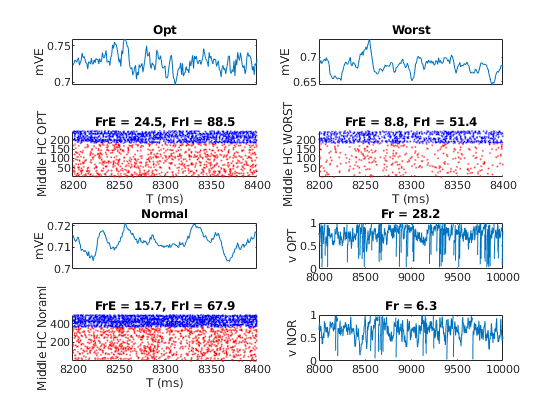

OptE = OD_E==1;           OptI = OD_I==1;
WorstE = OD_E==3;         WorstI = OD_I==3;
NorE = OD_E==2 | OD_E==4; NorI = OD_I==2 | OD_I==4;

MidColE = NnE.X>=1.25*n_E_HC & NnE.X<=1.75*n_E_HC;
MidRowE = NnE.Y>=1.25*n_E_HC & NnE.Y<=1.75*n_E_HC;
MidHCE = MidColE & MidRowE;

MidColI = NnI.X>=1.25*n_I_HC & NnI.X<=1.75*n_I_HC;
MidRowI = NnI.Y>=1.25*n_I_HC & NnI.Y<=1.75*n_I_HC;
MidHCI= MidColI & MidRowI;

ShowWin = [8200 8400];
figure('Name','Domain Range')

OD1E = find(OptE & MidHCE);
OD1I = find(OptI & MidHCI);
scatter1E = find(ismember(SpE(:,1),OD1E));
scatter1I = find(ismember(SpI(:,1),OD1I));
[~,OD1E_Ind] = ismember(SpE(scatter1E,1),OD1E);
[~,OD1I_Ind] = ismember(SpI(scatter1I,1),OD1I);
subplot 423
hold on
scatter(SpE(scatter1E,2),OD1E_Ind,0.5,'r.')
scatter(SpI(scatter1I,2),OD1I_Ind+max(OD1E_Ind),0.5,'b.');  
FrE1 = length(SpE(scatter1E,2))/(T/1e3)/length(OD1E);
FrI1 = length(SpI(scatter1I,2))/(T/1e3)/length(OD1I);
title(sprintf('FrE = %.1f, FrI = %.1f',FrE1,FrI1))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 421
plot(StatWin(1:WinNum),nanmean(mVE(OD1E,:)))
ylabel('mVE')
set(gca,'xtick','')
title('Opt')
xlim(ShowWin)

OD2E = find(WorstE & MidHCE);
OD2I = find(WorstI & MidHCI);
scatter2E = find(ismember(SpE(:,1),OD2E));
scatter2I = find(ismember(SpI(:,1),OD2I));
[~,OD2E_Ind] = ismember(SpE(scatter2E,1),OD2E);
[~,OD2I_Ind] = ismember(SpI(scatter2I,1),OD2I);
subplot 424
hold on
scatter(SpE(scatter2E,2),OD2E_Ind,0.5,'r.')
scatter(SpI(scatter2I,2),OD2I_Ind+max(OD2E_Ind),0.5,'b.'); 
FrE2 = length(SpE(scatter2E,2))/(T/1e3)/length(OD2E);
FrI2 = length(SpI(scatter2I,2))/(T/1e3)/length(OD2I);
title(sprintf('FrE = %.1f, FrI = %.1f',FrE2,FrI2))
xlabel('T (ms)'); ylabel('Middle HC WORST')
axis tight
xlim(ShowWin)
subplot 422
plot(StatWin(1:WinNum),nanmean(mVE(OD2E,:)))
ylabel('mVE')
set(gca,'xtick','')
title('Worst')
xlim(ShowWin)

OD3E = find(NorE & MidHCE);
OD3I = find(NorI & MidHCI);
scatter3E = find(ismember(SpE(:,1),OD3E));
scatter3I = find(ismember(SpI(:,1),OD3I));
[~,OD3E_Ind] = ismember(SpE(scatter3E,1),OD3E);
[~,OD3I_Ind] = ismember(SpI(scatter3I,1),OD3I);
subplot 427
hold on
scatter(SpE(scatter3E,2),OD3E_Ind,0.5,'r.')
scatter(SpI(scatter3I,2),OD3I_Ind+max(OD3E_Ind),0.5,'b.');  
FrE3 = length(SpE(scatter3E,2))/(T/1e3)/length(OD3E);
FrI3 = length(SpI(scatter3I,2))/(T/1e3)/length(OD3I);
title(sprintf('FrE = %.1f, FrI = %.1f',FrE3,FrI3))
xlabel('T (ms)'); ylabel('Middle HC Noraml')
axis tight
xlim(ShowWin)
subplot 425
plot(StatWin(1:WinNum),nanmean(mVE(OD_E'==2| OD_E'==4,:)))
ylabel('mVE')
set(gca,'xtick','')
title('Normal')
xlim(ShowWin)

% subplot 427
% hist(SpE(ismember(SpE(:,1),find(NorE & MidHCE)),2),0:1:T)
% xlabel('T (ms)'); ylabel('Spike count for all E cells')
% axis tight
% xlim(ShowWin)
% subplot 425
% plot(StatWin(1:WinNum),nanmean(mVE(OD_E'==2| OD_E'==4,:)))
% ylabel('mVE')
% set(gca,'xtick','')
% xlim(ShowWin)

subplot 426
hold on
NeuInd = OD1E(1);
OnOff = double(~logical(floor(mod(PhaseE(NeuInd)+tCorrect,tMod)/MaxOnPhase)));
plot(tCorrect+T,OnOff,'r')
plot(StatWin(1:WinNum),mVE(NeuInd,:))
xlim([8e3 10e3])
Fr1E1 = length(SpE(ismember(SpE(:,1),NeuInd),2))/(T/1e3)/1;
title(sprintf('Fr = %.1f',Fr1E1))
ylabel('v OPT')
subplot 428
hold on
NeuInd = OD2E(1);
OnOff = double(~logical(floor(mod(PhaseE(NeuInd)+tCorrect,tMod)/MaxOnPhase)));
plot(tCorrect+T,OnOff,'r')
plot(StatWin(1:WinNum),mVE(NeuInd,:))
xlim([8e3 10e3])
Fr1E2 = length(SpE(ismember(SpE(:,1),NeuInd),2))/(T/1e3)/1;
title(sprintf('Fr = %.1f',Fr1E2))
ylabel('v NOR')

% OD_EMapTry = OD_EMap;
% OD_EMapTry([1:54,109:161],:) = 0;
% OD_EMapTry(:,[1:54,109:161]) = 0;
% OptOne = find(OD_EMapTry(:)==1);
% hist(SpE(ismember(SpE(:,1),OptOne),2),0:1:T)

### Plot Spatial maps: Plot

WinSize = 7500;
Window = [T-WinSize T];
EffSize = Window(2)-max(0,Window(1));

tCorrect = linspace(-T,0,WinNum+1); % Use mV recording time grid
OnOffmV = ~logical(floor(mod(...
                                  repmat(PhaseE,1,WinNum+1)+repmat(tCorrect,N_E,1),...
                                  tMod)/MaxOnPhase));
OnOffSpE =  ~logical(floor(mod(...
                                  PhaseE(SpE(:,1))+SpE(:,2) - T,...
                                  tMod)/MaxOnPhase));

% PixelNum per HC
NPixX = 10; %10
NPixY = 10;

Figure for ONOFF

First create an onoff vec for each spike

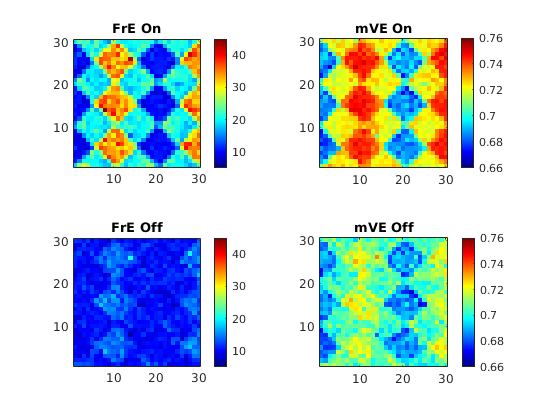


hFrVOnOff = figure('Name','Field_f&V');
subplot 221
ESPinWinOn = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2) & OnOffSpE;
SpEGoodOn = SpE(ESPinWinOn,1);
[SpCNOn, SpCIOn] = groupcounts(SpEGoodOn);
FrEOn_temp = zeros(N_E,1);
FrEOn_temp(SpCIOn) = SpCNOn*1e3/(EffSize/2);
[FrEOnPixMat,~] = NeuVec2Pixel(FrEOn_temp,NnE,NPixX*N_HC,NPixY*N_HC);
imagesc(FrEOnPixMat); title('FrE On')
set(gca,'YDir','normal')
axis square
colormap jet; caxis([5 45])
colorbar

subplot 223
ESPinWinOff = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2) & ~OnOffSpE;
SpEGoodOff = SpE(ESPinWinOff,1);
[SpCNOff, SpCIOff] = groupcounts(SpEGoodOff);
FrEOff_temp = zeros(N_E,1);
FrEOff_temp(SpCIOff) = SpCNOff*1e3/(EffSize/2);
[FrEOffPixMat,~] = NeuVec2Pixel(FrEOff_temp,NnE,NPixX*N_HC,NPixY*N_HC);
imagesc(FrEOffPixMat); title('FrE Off')
set(gca,'YDir','normal')
axis square
colormap jet ; caxis([5 45])
colorbar

Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
OnmVPhase = double(OnOffmV);
OnmVPhase(~OnOffmV) = nan;
subplot 222
mVEOn = mVE; mVEOn = mVEOn.*OnmVPhase(:,2:end);
mVEOn_temp = nanmean(mVEOn(:,SmallWinRange),2);

[mVEOnPixMat,~] = NeuVec2Pixel(mVEOn_temp,NnE,NPixX*N_HC,NPixY*N_HC);
imagesc(mVEOnPixMat); title('mVE On')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis([0.66 0.76])

OffmVPhase = double(~OnOffmV);
OffmVPhase(OnOffmV) = nan;
subplot 224
mVEOff = mVE; mVEOff = mVEOff.*OffmVPhase(:,2:end);
mVEOff_temp = nanmean(mVEOff(:,SmallWinRange),2);

[mVEOffPixMat,~] = NeuVec2Pixel(mVEOff_temp,NnE,NPixX*N_HC,NPixY*N_HC);
imagesc(mVEOffPixMat); title('mVE Off')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis([0.66 0.76])

Figure for All Average

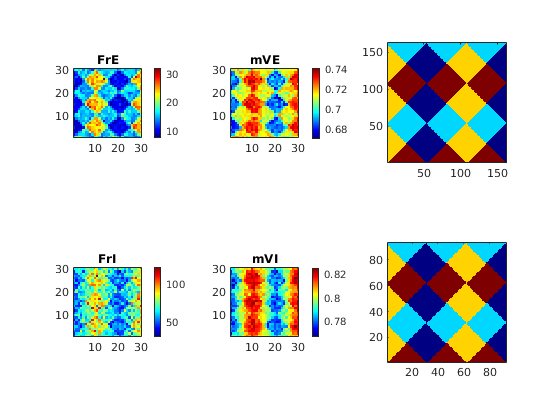

hFrVAll = figure('Name','Field_f&V');
subplot 231
ESPinWin = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2);
SpEGood = SpE(ESPinWin,1);
[SpCN, SpCI] = groupcounts(SpEGood);
FrE_temp = zeros(N_E,1);
FrE_temp(SpCI) = SpCN*1e3/(EffSize);
FrE_Map = reshape(FrE_temp,N_HC*n_E_HC,N_HC*n_E_HC); % not used here

[FrEPixMat,NnEPixel] = NeuVec2Pixel(FrE_temp,NnE,NPixX*N_HC,NPixY*N_HC);
imagesc(FrEPixMat); title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 234
ISPinWin = (SpI(:,2)>=Window(1) & SpI(:,2)<=Window(2));
SpIGood = SpI(ISPinWin,1);
[SpCN, SpCI] = groupcounts(SpIGood);
FrI_temp = zeros(N_I,1);
FrI_temp(SpCI) = SpCN*1e3/EffSize;
FrI_Map = reshape(FrI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[FrIPixMat,NnIPixel] = NeuVec2Pixel(FrI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
subplot 232
mVE_temp = nanmean(mVE(:,SmallWinRange),2);
mVE_Map = reshape(mVE_temp,N_HC*n_E_HC,N_HC*n_E_HC);

[mVEPixMat,~] = NeuVec2Pixel(mVE_temp,NnE,NPixX*N_HC,NPixY*N_HC);
imagesc(mVEPixMat); title('mVE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 235
mVI_temp = nanmean(mVI(:,SmallWinRange),2);
mVI_Map = reshape(mVI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[mVIPixMat,~] = NeuVec2Pixel(mVI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(mVIPixMat); title('mVI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

% Orientation domain
subplot 233
imagesc(OD_EMap);axis square
set(gca,'YDir','normal')

subplot 236
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')


% end of 500ms plot
OPT = find(OD_E == 1);
WORST = find(OD_E == 3);
MID = find(OD_E == 2 | OD_E == 4);
tCorrect = -T:dt:0;
hSpCount = figure('Name','SpCount')

hSpCount =   Figure (4: SpCount) with properties:

      Number: 4
        Name: 'SpCount'
       Color: [0.9400 0.9400 0.9400]
    Position: [1761 1399 560 420]
       Units: 'pixels'

  Show all properties


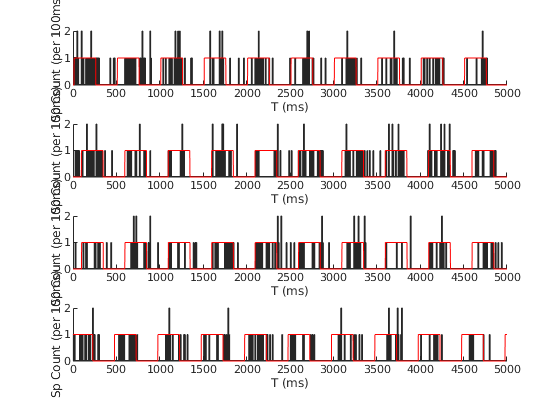

for subInd = 1:4
    subplot(4,1,subInd)
    NeuInd = OPT(subInd);
    hold on
    hist(SpE(ismember(SpE(:,1),NeuInd),2),0:10:T)
    OnOff = double(~logical(floor(mod(PhaseE(NeuInd)+tCorrect,tMod)/MaxOnPhase)));
    plot(tCorrect+T,OnOff,'r')
    xlim([0 5000])
    xlabel('T (ms)')
    ylabel('Sp Count (per 100ms)')
    
end

    


%save('DriveWkSp.mat')

## MF linear equation for pixels: 1 Matrices

PixNum = NPixX*N_HC * NPixY*N_HC;
% First, get connectivity matrix between Pixels
C_EE_Pixel = zeros(PixNum);
C_EI_Pixel = zeros(PixNum);
C_IE_Pixel = zeros(PixNum);
C_II_Pixel = zeros(PixNum);
% look into std as well
C_EE_Pixelstd = zeros(PixNum);
C_EI_Pixelstd = zeros(PixNum);
C_IE_Pixelstd = zeros(PixNum);
C_II_Pixelstd = zeros(PixNum);
tic
AA = PixNum;
parfor PixIndPost = 1:AA
    for PixIndPre = 1:AA
        C_EE_Pixel(PixIndPost,PixIndPre) = mean(sum(C_EE_Fix_Bd(NnEPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_EI_Pixel(PixIndPost,PixIndPre) = mean(sum(C_EI_Fix_Bd(NnEPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_IE_Pixel(PixIndPost,PixIndPre) = mean(sum(C_IE_Fix_Bd(NnIPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_II_Pixel(PixIndPost,PixIndPre) = mean(sum(C_II_Fix_Bd(NnIPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_EE_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_EE_Fix_Bd(NnEPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_EI_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_EI_Fix_Bd(NnEPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_IE_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_IE_Fix_Bd(NnIPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_II_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_II_Fix_Bd(NnIPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
    end    
end

Starting parallel pool (parpool) using the 'local' profile ...


toc
C_EE_Pixel_Us = sparse(C_EE_Pixel);
C_IE_Pixel_Us = sparse(C_IE_Pixel);
C_EI_Pixel_Us = sparse(C_EI_Pixel);
C_II_Pixel_Us = sparse(C_II_Pixel);

% Present connectivity mats
figure
subplot 221
imagesc(C_EE_Pixel)
colormap jet
colorbar
axis square
title('Mean of connectivities')
subplot 222
imagesc(C_EE_Pixelstd)
axis square
colorbar
title('Std of connectivities')
subplot 223
imagesc(C_EE_Pixelstd./C_EE_Pixel)
axis square
colorbar
title('std/mean')

MF linear equation for pixels: 2 MF Eqns

FrEPixVec = reshape(FrEPixMat,PixNum,1);
FrEOnPixVec  = reshape(FrEOnPixMat,PixNum,1);
FrEOffPixVec = reshape(FrEOffPixMat,PixNum,1);
FrIPixVec = reshape(FrIPixMat,PixNum,1);

mVEPixVec = reshape(mVEPixMat,PixNum,1);
mVEOnPixVec  = reshape(mVEOnPixMat,PixNum,1);
mVEOffPixVec = reshape(mVEOffPixMat,PixNum,1);
mVIPixVec = reshape(mVIPixMat,PixNum,1);


% Mats
MatEE = (S_EE*(1-p_EEFail))*full(C_EE_Pixel_Us); % Need Ref here??
MatEI = S_EI *              full(C_EI_Pixel_Us);
MatIE = S_IE *              full(C_IE_Pixel_Us).*(Ve-repmat(mVIPixVec,1,PixNum));
MatII = S_II *              full(C_II_Pixel_Us).*(Vi-repmat(mVIPixVec,1,PixNum));
ConnMat = [MatEE.*(Ve-repmat(mVEOnPixVec,1,PixNum))/2 , MatEE.*(Ve-repmat(mVEOnPixVec,1,PixNum))/2 , MatEI.*(Vi-repmat(mVEOnPixVec,1,PixNum));
           MatEE.*(Ve-repmat(mVEOffPixVec,1,PixNum))/2, MatEE.*(Ve-repmat(mVEOffPixVec,1,PixNum))/2, MatEI.*(Vi-repmat(mVEOffPixVec,1,PixNum));
           MatIE/2                                    , MatIE/2                                    , MatII];
% Leak On/Off
LeakEOn  = gL_E * (0-mVEOnPixVec)  * 1e3;
LeakEOff = gL_E * (0-mVEOffPixVec) * 1e3;
LeakI =    gL_I * (0-mVIPixVec)    * 1e3;
LeakV = [LeakEOn;LeakEOff;LeakI];
% Ext
lambda_EOn_Pixel = zeros(size(mVEPixVec));
lambda_EOff_Pixel = zeros(size(mVEPixVec));
L6E_Pixel = zeros(size(mVEPixVec));
L6I_Pixel = zeros(size(mVEPixVec));
for PixInd = 1:PixNum
    lambda_EOn_Pixel(PixInd)  = mean(lambda_EOn_drive(NnEPixel.Vec == PixInd));
    lambda_EOff_Pixel(PixInd) = mean(lambda_EOff_drive(NnEPixel.Vec == PixInd));
    L6E_Pixel(PixInd) = mean(rE_L6_Drive(NnEPixel.Vec == PixInd));
    L6I_Pixel(PixInd) = mean(rI_L6_Drive(NnIPixel.Vec == PixInd));
end
lambda_I_Pixel = lambda_I_drive;

ExtEOn  = (lambda_EOn_Pixel*S_Elgn  + rE_amb*S_amb + L6E_Pixel*S_EL6).*(Ve-mVEOnPixVec ) * 1e3;
ExtEOff = (lambda_EOff_Pixel*S_Elgn + rE_amb*S_amb + L6E_Pixel*S_EL6).*(Ve-mVEOffPixVec) * 1e3;
ExtI =    (lambda_I_Pixel*S_Ilgn    + rI_amb*S_amb + L6I_Pixel*S_IL6).*(Ve-mVIPixVec)    * 1e3;
ExtV = [ExtEOn;ExtEOff;ExtI];
% Ref Vec
RefEOn = 1-FrEOnPixVec*tau_ref/1e3;
RefEOff = 1-FrEOffPixVec*tau_ref/1e3;
RefI = 1-FrIPixVec*tau_ref/1e3;
RefM = diag([RefEOn;RefEOff;RefI]);
% L4 Frs
Fr_L4 = [FrEOnPixVec; FrEOffPixVec; FrIPixVec];

% MF Equations:
%Fr_MF = RefM * (ConnMat*Fr_L4 + ExtV + LeakV);
tic
Fr_MFinv = (eye(3*PixNum)-RefM*ConnMat) \ (RefM * ( ExtV + LeakV));
toc

Elapsed time is 0.252135 seconds.


% Err
FrErr = Fr_MFinv - Fr_L4;

Scatter MF Rslt

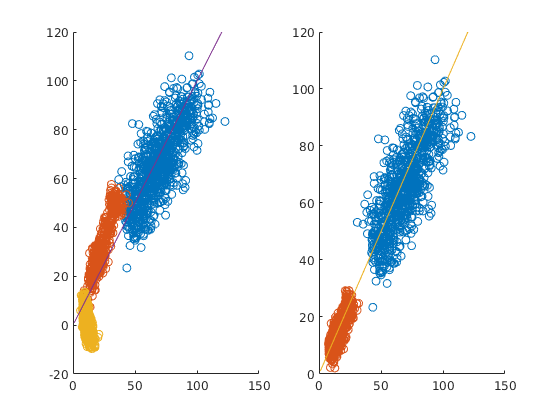

SC = Fr_MFinv;
figure
subplot 121
hold on
scatter(FrIPixVec, SC(1801:2700))
scatter(FrEOnPixVec, SC(1:900))
scatter(FrEOffPixVec, SC(901:1800))
plot(1:120, 1:120)

subplot 122
hold on
scatter(FrIPixVec, SC(1801:2700))
scatter(FrEPixVec, (SC(1:900)+SC(901:1800))/2 )
plot(1:120, 1:120)

Plot MF Rslt

EPixRange = [0 35];
IPixRange = [10 120]

IPixRange =     10   120



figure('Name','MF and Real Fr')
a1 = subplot (241);
PS = get(a1,'Position');
imagesc(FrEPixMat); title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 30])
set(a1,'Position',PS)
caxis(EPixRange);

a5 = subplot (245);
PS = get(a5,'Position');
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 80])
set(a5,'Position',PS)
caxis(IPixRange);

a2 = subplot (242);
PS = get(a2,'Position');
FrEPixMat_MF = (reshape(Fr_MFinv(1:PixNum),NPixY*N_HC,NPixX*N_HC) + ...
               reshape(Fr_MFinv(PixNum+1:2*PixNum),NPixY*N_HC,NPixX*N_HC))/2;
imagesc(FrEPixMat_MF); title('FrE_{MF}')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 30])
set(a2,'Position',PS)
caxis(EPixRange);

a6 = subplot (246);
PS = get(a6,'Position');
FrIPixMat_MF = reshape(Fr_MFinv(2*PixNum+1:end),NPixY*N_HC,NPixX*N_HC)

FrIPixMat_MF =    48.8986   54.6635   49.3417   58.0354   58.0233   58.5458   71.0355   65.2166   63.0504   74.5107   80.0583   60.7566   92.2412   79.1528   73.3396   51.3493   50.4344   52.7972   66.1158   49.8488   41.9012   79.3706   59.2356   61.8434   74.1593   66.4037   74.3795   71.6140   63.6882   88.1087
   45.1199   43.1037   62.2317   65.2913   65.7098   67.9830   71.3070   67.1073   62.3187   88.6458   95.5034   77.7535   60.8596   65.3275   69.0378   69.7001   51.7271   65.4612   61.9010   23.4103   47.6472   49.6269   60.1918   69.8208   60.2825   74.1181   68.2154   59.7311   75.3701   91.5057
   44.0211   49.9717   55.3941   72.9237   71.6319   57.3272   45.0021   64.1591   84.5827   95.3670   82.0500   82.6505   74.7570   62.3779   66.5066   70.0810   55.1361   67.0158   32.5787   56.4410   49.7883   39.2674   55.6432   74.4666   68.2050   61.6469   57.8894   78.2173  101.4963   81.4992
   58.4863   55.2929   47.5856   53.3105   76.9525   62.0122   74.9818   93.7133  

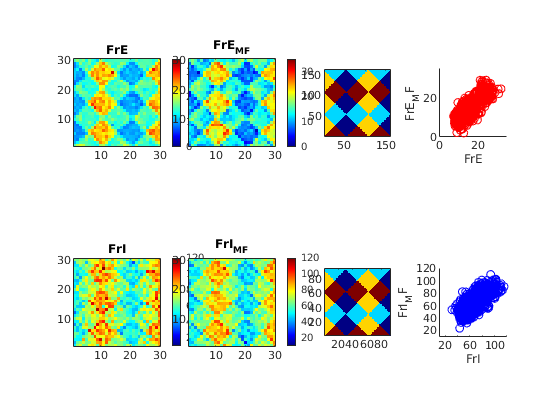

imagesc(FrIPixMat_MF); title('FrI_{MF}')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 80])
set(a6,'Position',PS)
caxis(IPixRange);

subplot 243
imagesc(OD_EMap);axis square
set(gca,'YDir','normal')

subplot 247
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')

subplot 244
scatter(FrEPixVec,(Fr_MFinv(1:PixNum) + Fr_MFinv(PixNum+1:2*PixNum))/2,'ro')
axis([EPixRange EPixRange])
axis square
xlabel('FrE'); ylabel('FrE_MF')

subplot 248
scatter(FrIPixVec,Fr_MFinv(2*PixNum+1:end),'bo')
 axis([IPixRange IPixRange])
axis square
xlabel('FrI'); ylabel('FrI_MF')

Result not very good. On the other hand, should concern real input since we are only averaging from 25/8 neurons?

Check code: Mistakes in row and column?